# **第2回 レポート課題**

## 課題１．SVMによるWineデータのクラス分類

[https://archive.ics.uci.edu/ml/datasets/Wine](https://manaba.tsukuba.ac.jp/ct/link_iframe_balloon?url=https%3A%2F%2Farchive.ics.uci.edu%2Fml%2Fdatasets%2FWine)

上記のURLからwine.data，wine.namesをダウンロードする．

wine.csvをダブルクリックして出力形式を数値行列として，インポートする．

ワークスペースに数値行列(178*14)のwineがあることを確認する．

その後，「wine.mat」として保存する．

入力特徴量にAlcohol，Malic acidの２つの特徴量を用いる．

まずは，２クラスの分類を行う．

load('wine.mat');
indices = 1:130;
X = wine(indices,2:3);
Y = wine(indices,1);

可視化してみる．

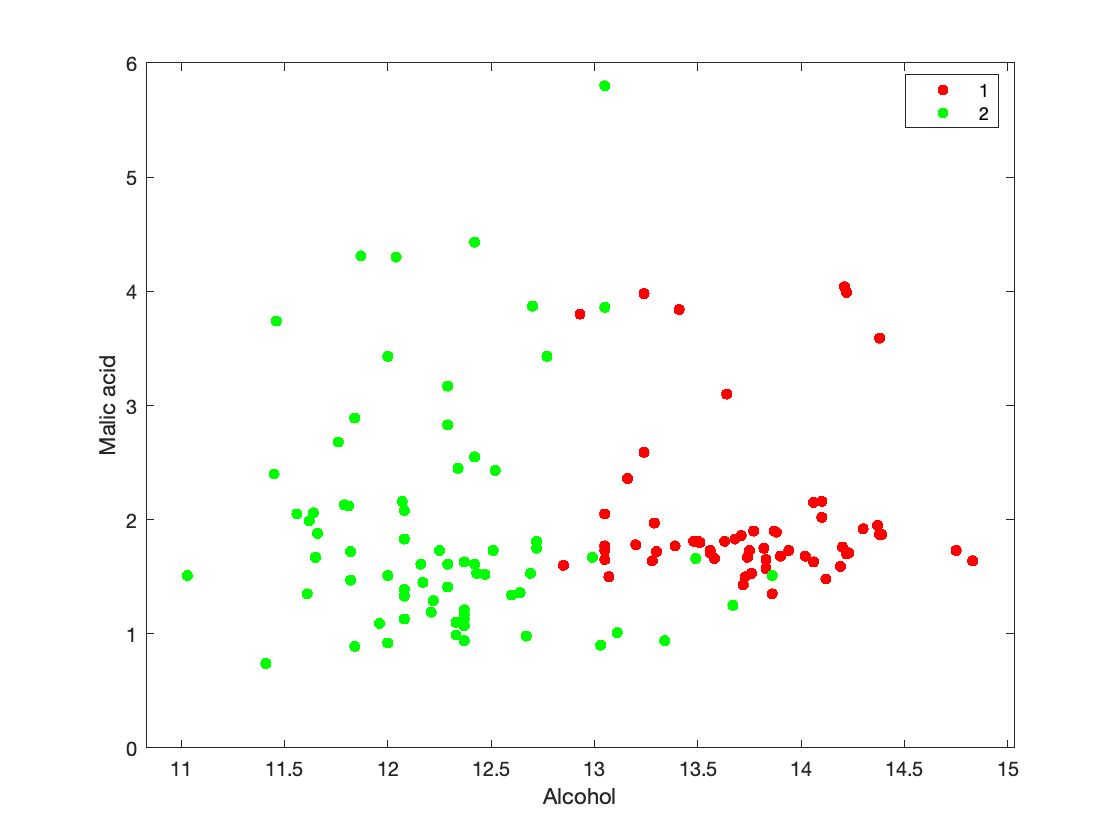

gscatter(X(:,1), X(:,2), Y, 'rgb');
xlabel('Alcohol')
ylabel('Malic acid')

ここでは，アプリからエクスポートした学習済みの線形SVMを用いて，1行目のデータを予測してみる．

trainedModel.predictFcn(X(1,:))
Y(1,:)

ans = 1

学習済みモデルが正解のラベルを出力していることがわかる．

ここからは，コマンドベースでSVMモデルの構築を行う．

まずは，ソフトマージン(C=1)の線形SVMによる分類を行う．

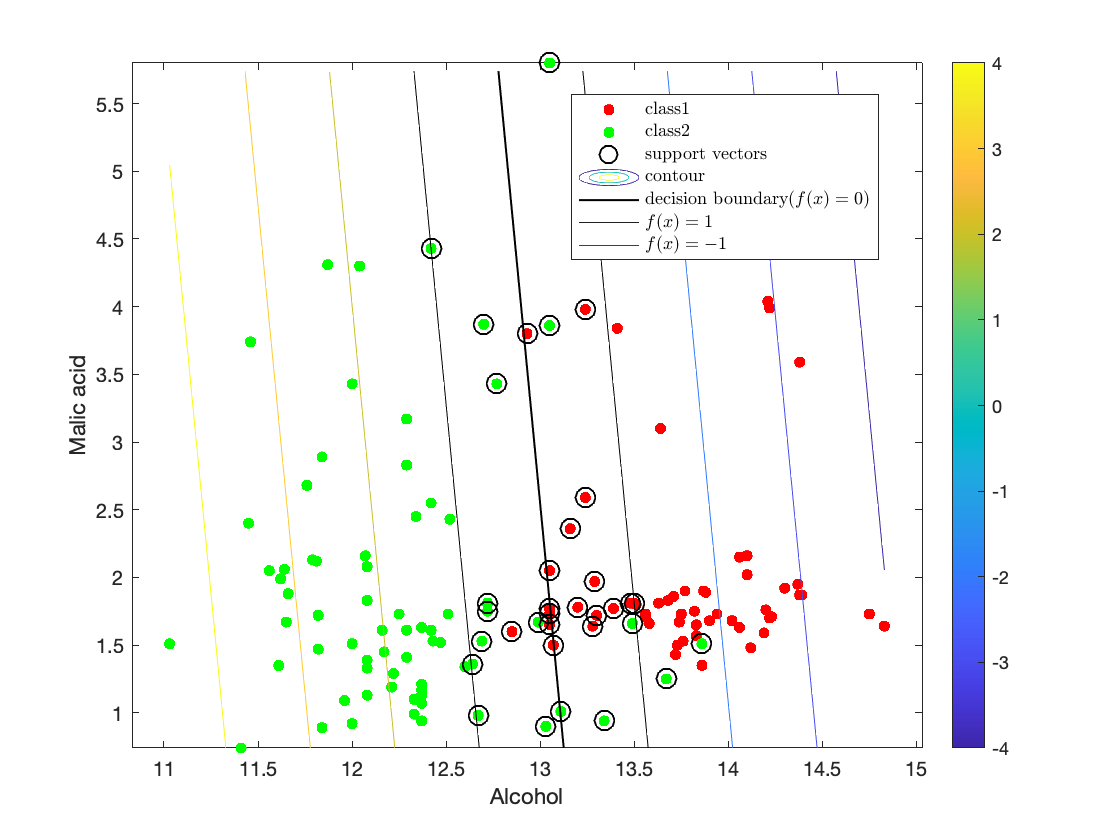

SVMModel = fitcsvm(X,Y, "BoxConstraint", 1);
svInd = SVMModel.IsSupportVector; 
h = 0.1; % Mesh grid step size
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)), min(X(:,2)):h:max(X(:,2))); % calculate grid points
[~,score] = SVMModel.predict([X1(:),X2(:)]);  % calculate scores at the each grid point
scoreGrid = reshape(score(:,2),size(X1,1),size(X2,2)); 
figure
gscatter(X(:,1), X(:,2), Y, 'rg');
hold on
plot(X(svInd,1),X(svInd,2),'ko','MarkerSize',10, "LineWidth",1) % Mark support vectors
contour(X1,X2,scoreGrid); % draw contour 
contour(X1,X2,scoreGrid, [0 0],'k', "LineWidth", 1); %draw decision bounday
contour(X1,X2,scoreGrid, [1 1],'k'); %draw f(x)=1
contour(X1,X2,scoreGrid, [-1 -1],'k'); %draw f(x)=-1
colorbar;
xlabel('Alcohol')
ylabel('Malic acid')
legend(["class1", "class2", "support vectors", "contour", "decision boundary($f(x)=0$)", "$f(x)=1$", "$f(x)=-1$"], "Interpreter","latex");
hold off

次に，C=1からC=1000と値を大きくして，ハードマージンによる分類を試してみる．

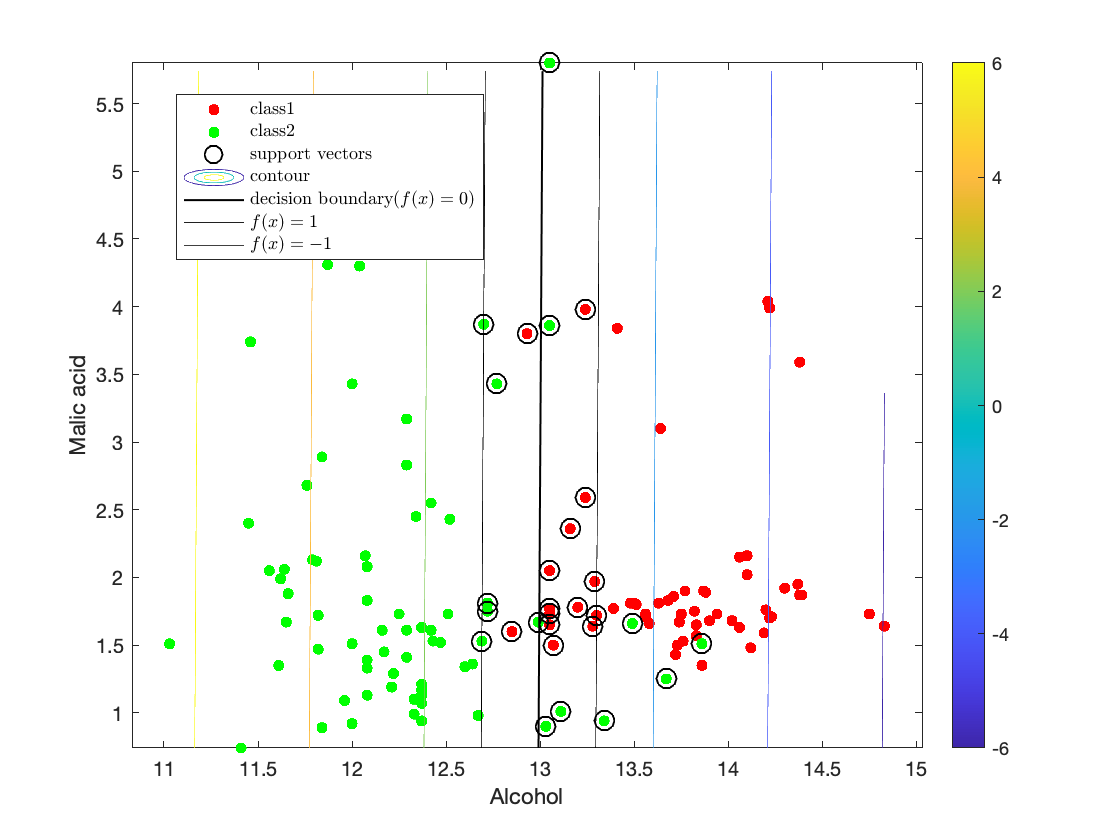

SVMModel = fitcsvm(X,Y, "BoxConstraint", 1000);
svInd = SVMModel.IsSupportVector; 
h = 0.1; % Mesh grid step size
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)), min(X(:,2)):h:max(X(:,2))); % calculate grid points
[~,score] = SVMModel.predict([X1(:),X2(:)]);  % calculate scores at the each grid point
scoreGrid = reshape(score(:,2),size(X1,1),size(X2,2)); 
figure
gscatter(X(:,1), X(:,2), Y, 'rg');
hold on
plot(X(svInd,1),X(svInd,2),'ko','MarkerSize',10, "LineWidth",1) % Mark support vectors
contour(X1,X2,scoreGrid); % draw contour 
contour(X1,X2,scoreGrid, [0 0],'k', "LineWidth", 1); %draw decision bounday
contour(X1,X2,scoreGrid, [1 1],'k'); %draw f(x)=1
contour(X1,X2,scoreGrid, [-1 -1],'k'); %draw f(x)=-1
colorbar;
xlabel('Alcohol')
ylabel('Malic acid')
legend(["class1", "class2", "support vectors", "contour", "decision boundary($f(x)=0$)", "$f(x)=1$", "$f(x)=-1$"], "Interpreter", "latex");
hold off

ハードマージンによるSVMを用いても，未だに誤分類が見られる．

線形SVMによる直線の境界線では，分類が難しいため，次に，RBFカーネルを用いたSVMを適用する．

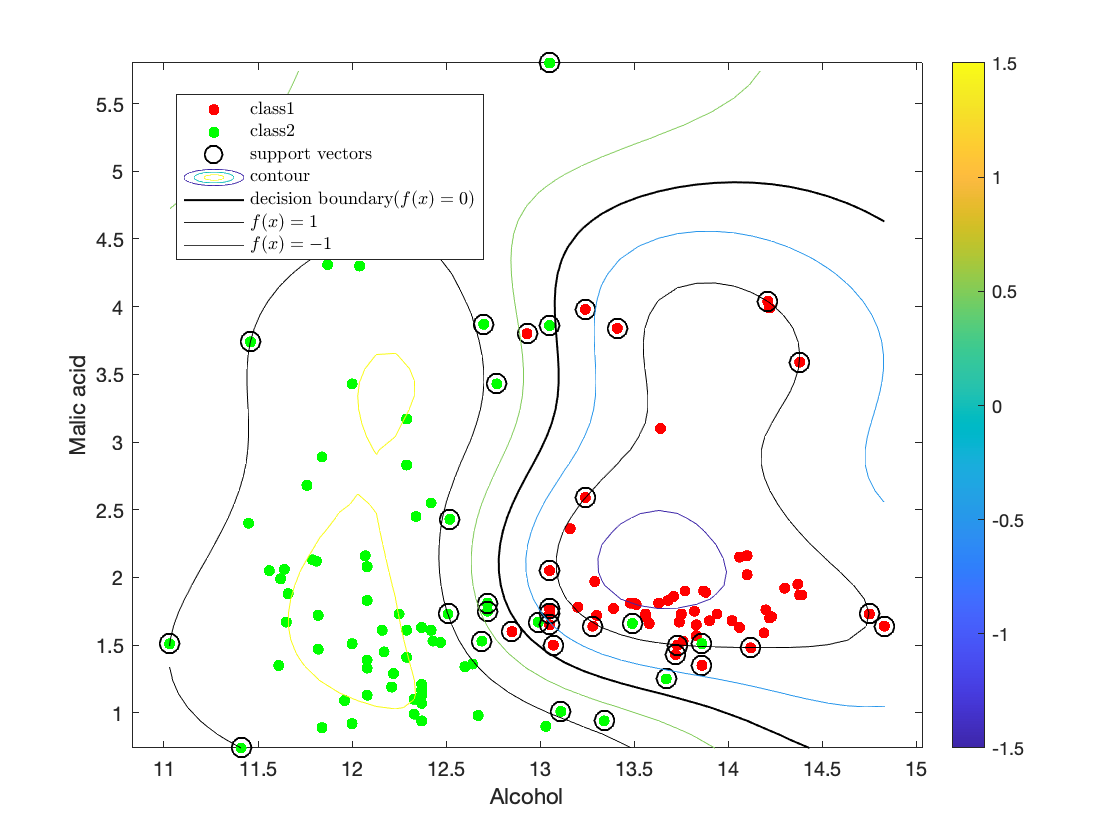

SVMModel = fitcsvm(X,Y, "BoxConstraint", 1, "KernelFunction", "gaussian");
svInd = SVMModel.IsSupportVector; 
h = 0.1; % Mesh grid step size
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)), min(X(:,2)):h:max(X(:,2))); % calculate grid points
[~,score] = SVMModel.predict([X1(:),X2(:)]);  % calculate scores at the each grid point
scoreGrid = reshape(score(:,2),size(X1,1),size(X2,2)); 
figure
gscatter(X(:,1), X(:,2), Y, 'rg');
hold on
plot(X(svInd,1),X(svInd,2),'ko','MarkerSize',10, "LineWidth",1) % Mark support vectors
contour(X1,X2,scoreGrid); % draw contour 
contour(X1,X2,scoreGrid, [0 0],'k', "LineWidth", 1); %draw decision bounday
contour(X1,X2,scoreGrid, [1 1],'k'); %draw f(x)=1
contour(X1,X2,scoreGrid, [-1 -1],'k'); %draw f(x)=-1
colorbar;
xlabel('Alcohol')
ylabel('Malic acid')
legend(["class1", "class2", "support vectors", "contour", "decision boundary($f(x)=0$)", "$f(x)=1$", "$f(x)=-1$"], "Interpreter","latex");
hold off

線形SVMによる分類より，RBFカーネルを用いたSVMの方が上手く分類できているが，多少の誤分類が含まれる結果となった．

今度は，２クラスではなく，多クラス（＝３クラス）の分類を行う．

clear;
load('wine.mat');
X = wine(:,2:3);
Y = wine(:,1);

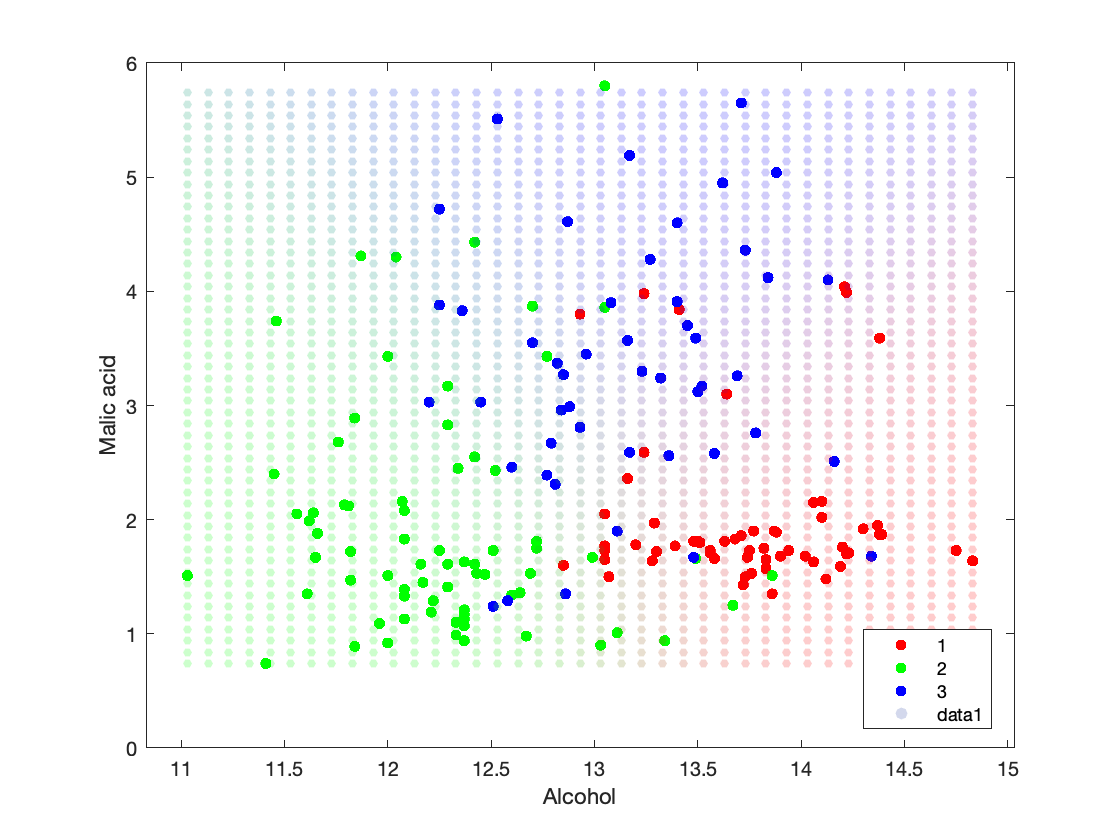

SVMModel = fitcecoc(X, Y, 'FitPosterior',true);
SVMModel.predict(X(1,:));
gscatter(X(:,1), X(:,2), Y, 'rgb');
hold on;
h=0.1;
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)), min(X(:,2)):h:max(X(:,2))); 
[~,~,~, posteriors]  = SVMModel.predict([X1(:), X2(:)]);  % calculate scores at the each grid point
scatter(X1(:), X2(:) , 20, posteriors, "filled", "MarkerFaceAlpha", 0.2);
xlabel('Alcohol')
ylabel('Malic acid')
hold off;

各クラスにおいて，誤分類が多く見られる．

そこで，前回の講義で扱ったPCAを用いて，標準化した入力特徴量を次元削減した後，SVMによる分類を試みる．

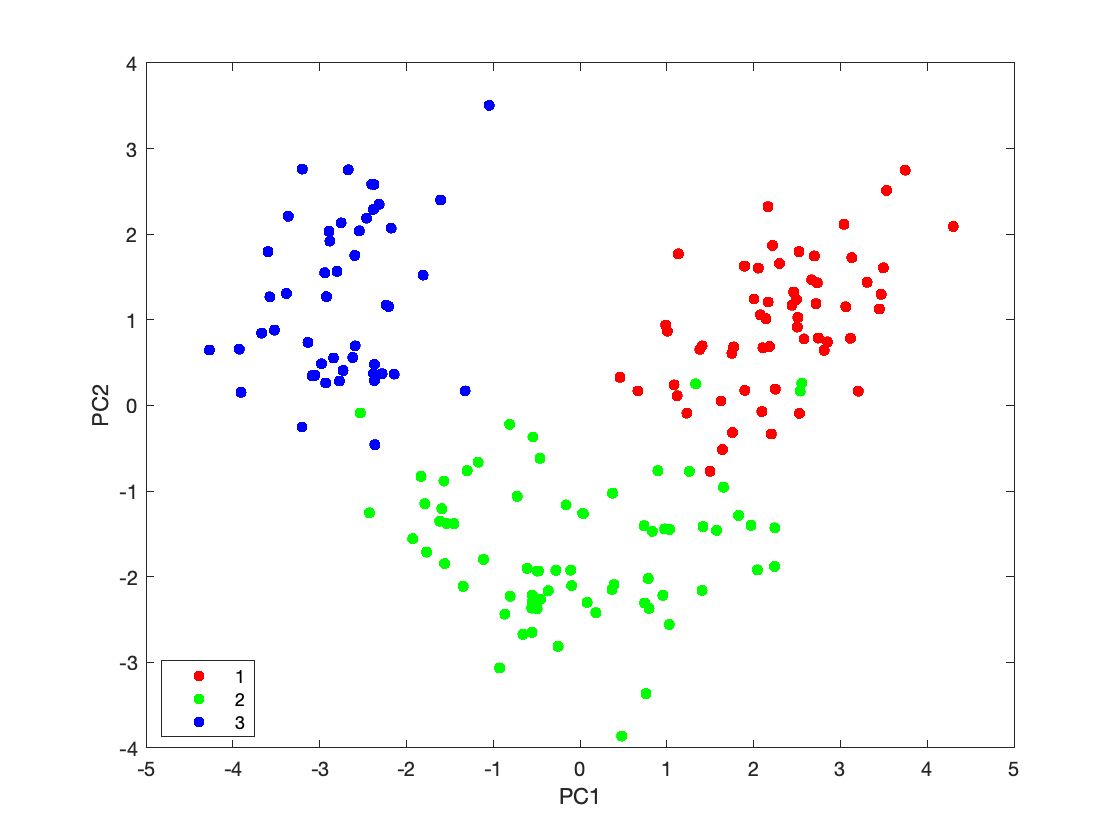

x = normalize(wine(:,2:end));
y = wine(:,1);
[coeff, score, latent, ~, explained, mu] = pca(x);
score;
figure;
gscatter(score(:,1), score(:,2), y, 'rgb');
xlabel('PC1');
ylabel('PC2');

まずは，第一主成分，第二主成分を用いて，２クラスの分類を試してみる．

indices = 1:130;
X = score(indices,1:2);
Y = y(indices,1);

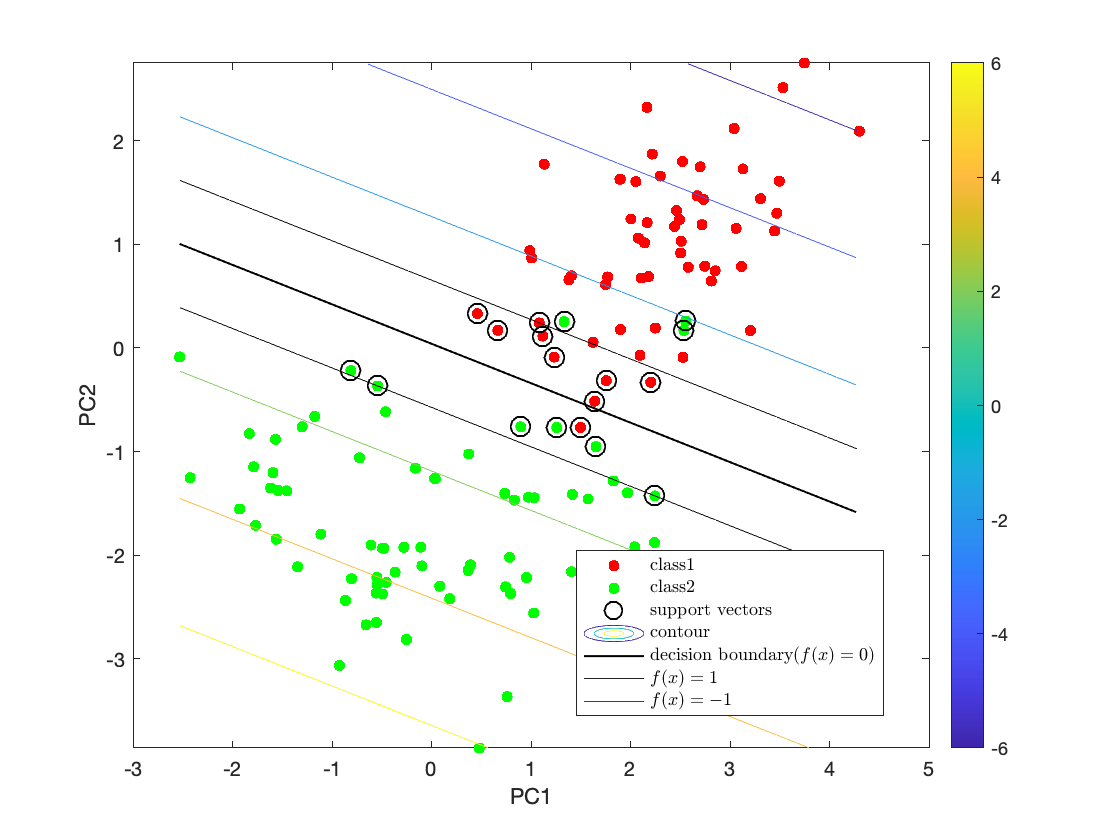

SVMModel = fitcsvm(X,Y, "BoxConstraint", 1);
svInd = SVMModel.IsSupportVector; 
h = 0.1; % Mesh grid step size
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)), min(X(:,2)):h:max(X(:,2))); % calculate grid points
[~,score_] = SVMModel.predict([X1(:),X2(:)]);  % calculate scores at the each grid point
scoreGrid = reshape(score_(:,2),size(X1,1),size(X2,2)); 
figure
gscatter(X(:,1), X(:,2), Y, 'rg');
hold on
plot(X(svInd,1),X(svInd,2),'ko','MarkerSize',10, "LineWidth",1) % Mark support vectors
contour(X1,X2,scoreGrid); % draw contour 
contour(X1,X2,scoreGrid, [0 0],'k', "LineWidth", 1); %draw decision bounday
contour(X1,X2,scoreGrid, [1 1],'k'); %draw f(x)=1
contour(X1,X2,scoreGrid, [-1 -1],'k'); %draw f(x)=-1
colorbar;
xlabel('PC1')
ylabel('PC2')
legend(["class1", "class2", "support vectors", "contour", "decision boundary($f(x)=0$)", "$f(x)=1$", "$f(x)=-1$"], "Interpreter","latex");
hold off

直線の境界線は引けないので，線形分類は難しそうである．

今度は，マルチクラスで行う．

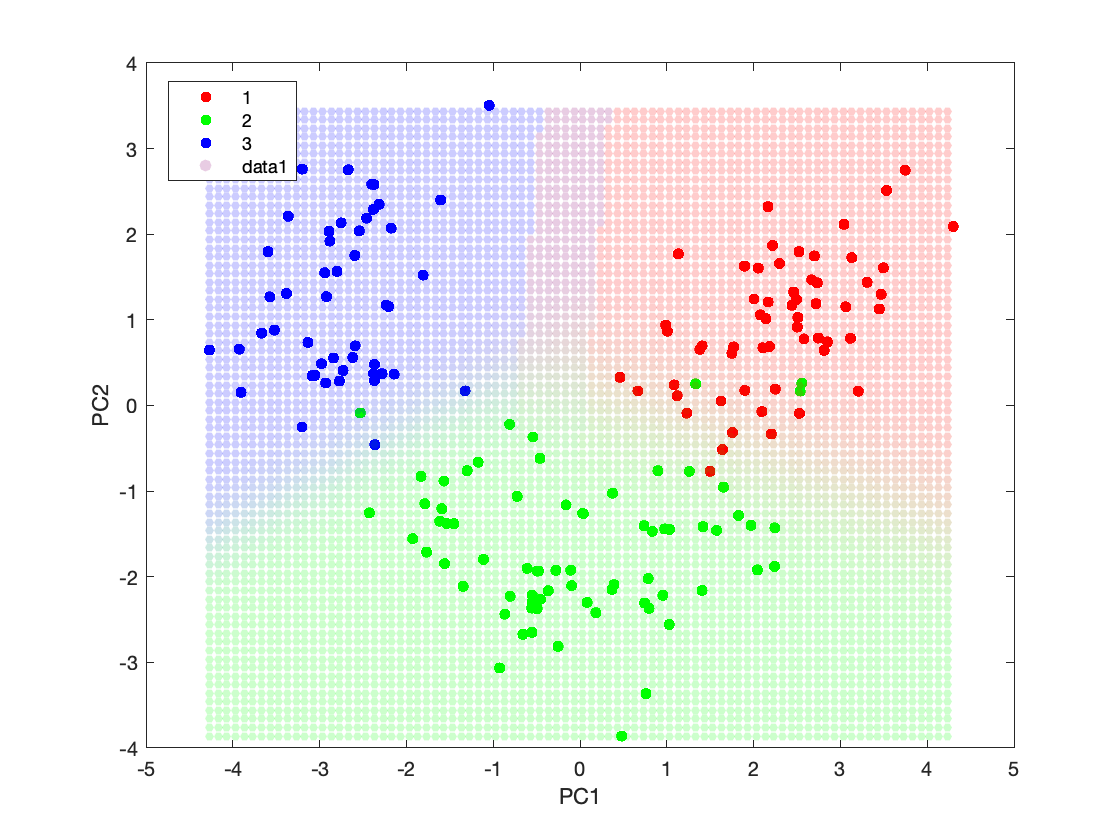

X = score(:,1:2);
Y = y(:,1);
SVMModel = fitcecoc(X, Y, 'FitPosterior',true);
SVMModel.predict(X(1,:));
gscatter(X(:,1), X(:,2), Y, 'rgb');
hold on;
h=0.1;
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)), min(X(:,2)):h:max(X(:,2))); 
[~,~,~, posteriors]  = SVMModel.predict([X1(:), X2(:)]);  % calculate scores at the each grid point
scatter(X1(:), X2(:) , 20, posteriors, "filled", "MarkerFaceAlpha", 0.2);
xlabel('PC1')
ylabel('PC2')
hold off;

プロットした図をみると，全体的に上手く境界線が引けるように３クラスの分類ができている．特に，青色と赤色の点でプロットされたクラス１とクラス３の誤分類は，あまり見られない．

PCAを用いずにSVMで分類した結果と比較しても，PCAを用いて次元削減して，SVMで分類する方が良いことがわかる．標準化した入力特徴量を，PCAを用いて次元削減した後，SVMにより分類することで，非常に上手く分類を行うことができた．

## 課題2．授業の感想

　授業の演習・課題を通して，SVMの理論及び実践的な使い方まで習得することができた．特に，前回の講義であつかったPCAによる次元削減をSVMと組み合わせることで，効率良く分類問題を扱えることが分かって楽しかった．講義で扱う内容が，次の項目と密接に繋がっており，順序良く講義の順番を組んでいただいていると思った．

　現在の画像認識・自然言語処理などの多くの分類問題の解法の主流は，ニューラルネットワークによる深層学習だが，分類するのが安易そうなデータセットやデータ量が少ない場合に対しては，SVMによる分類は十分有効だと思うので，CPUでも早く学習が可能なSVMは，一つの選択肢として今後も使えると思う．

## 課題３． 自身で用意したデータセットでのSVMによる分類

[https://www.kaggle.com/uciml/breast-cancer-wisconsin-data](https://www.kaggle.com/uciml/breast-cancer-wisconsin-data)

上記URLの乳がんのデータセットを使う．

５６９人の被験者に対して，１列目にID，２列目に診断結果(良性:B/悪性:M)，３列目以降は様々な計測値が格納されている．

ここでは，標準化した入力特徴量を，PCAにより次元削減し，第一主成分と第二主成分から，診断結果(良性:B/悪性:M)をSVMで分類することを試みる．

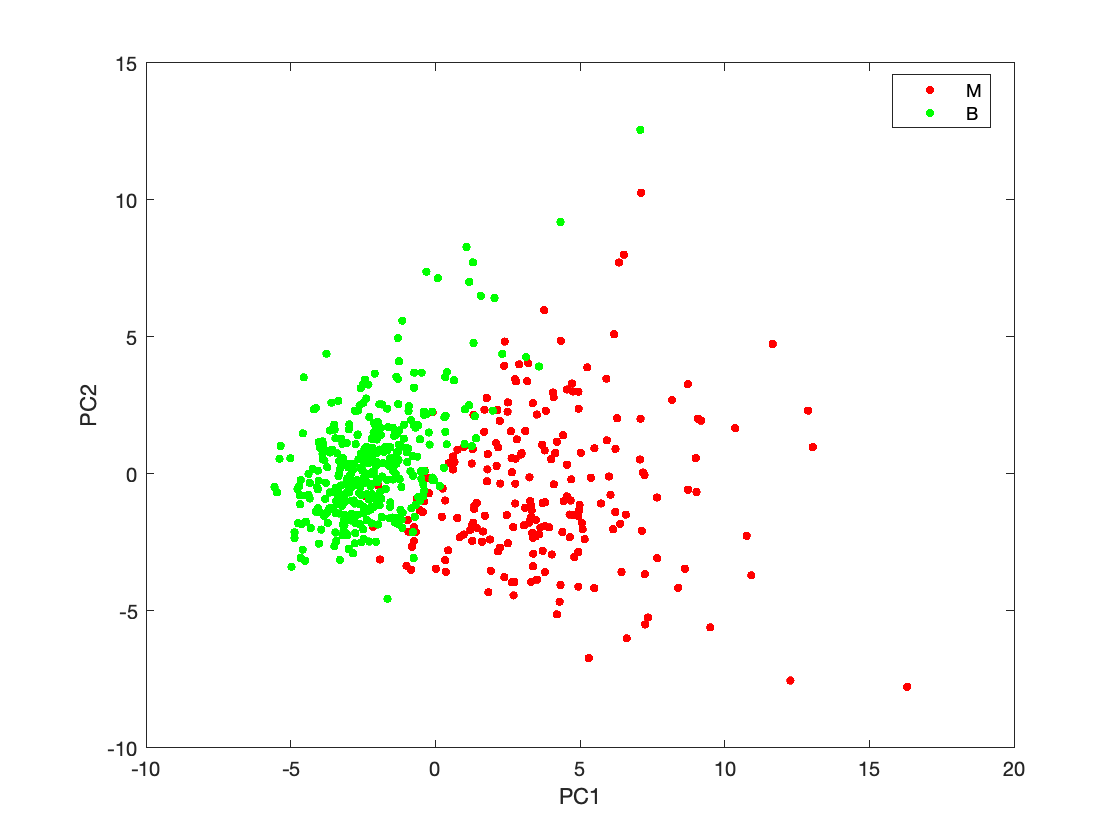

clear;
data = readmatrix('data.csv');
data(:,3:end);
X = normalize(data(:,3:end));
s = readtable('data.csv');
Y = string(s{:,2});
[coeff, score, latent, ~, explained, mu] = pca(X);
figure;
gscatter(score(:,1), score(:,2), Y, 'rg');
xlabel('PC1');
ylabel('PC2');

まずは，ソフトマージン(C=1)の線形SVMによる分類を行う．

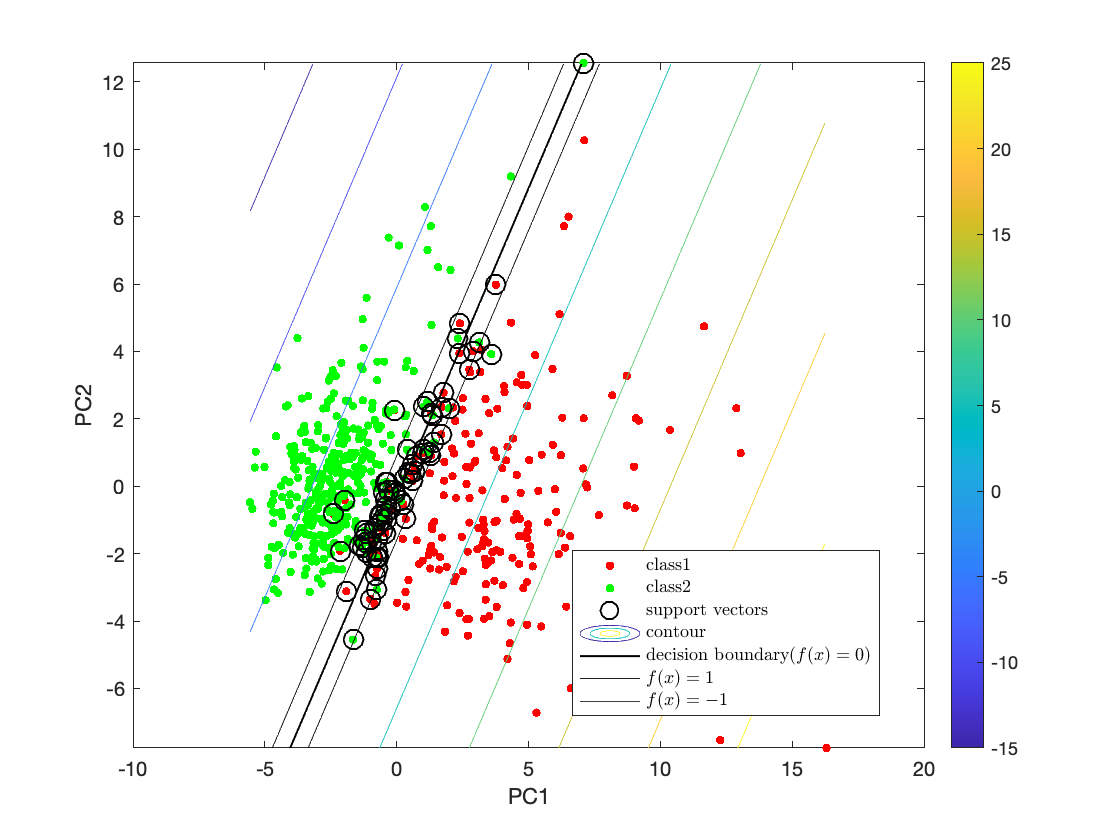

X = score(:,1:2);
SVMModel = fitcsvm(X,Y, "BoxConstraint", 1);
svInd = SVMModel.IsSupportVector; 
h = 0.1; % Mesh grid step size
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)), min(X(:,2)):h:max(X(:,2))); % calculate grid points
[~,score] = SVMModel.predict([X1(:),X2(:)]);  % calculate scores at the each grid point
scoreGrid = reshape(score(:,2),size(X1,1),size(X2,2)); 
figure
gscatter(X(:,1), X(:,2), Y, 'rg');
hold on
plot(X(svInd,1),X(svInd,2),'ko','MarkerSize',10, "LineWidth",1) % Mark support vectors
contour(X1,X2,scoreGrid); % draw contour 
contour(X1,X2,scoreGrid, [0 0],'k', "LineWidth", 1); %draw decision bounday
contour(X1,X2,scoreGrid, [1 1],'k'); %draw f(x)=1
contour(X1,X2,scoreGrid, [-1 -1],'k'); %draw f(x)=-1
colorbar;
xlabel('PC1')
ylabel('PC2')
legend(["class1", "class2", "support vectors", "contour", "decision boundary($f(x)=0$)", "$f(x)=1$", "$f(x)=-1$"], "Interpreter","latex");
hold off

線形SVMによる直線の境界線では，分類が難しいため，次に，カーネルにガウスを採用したRBFカーネルを用いたSVMを適用する．

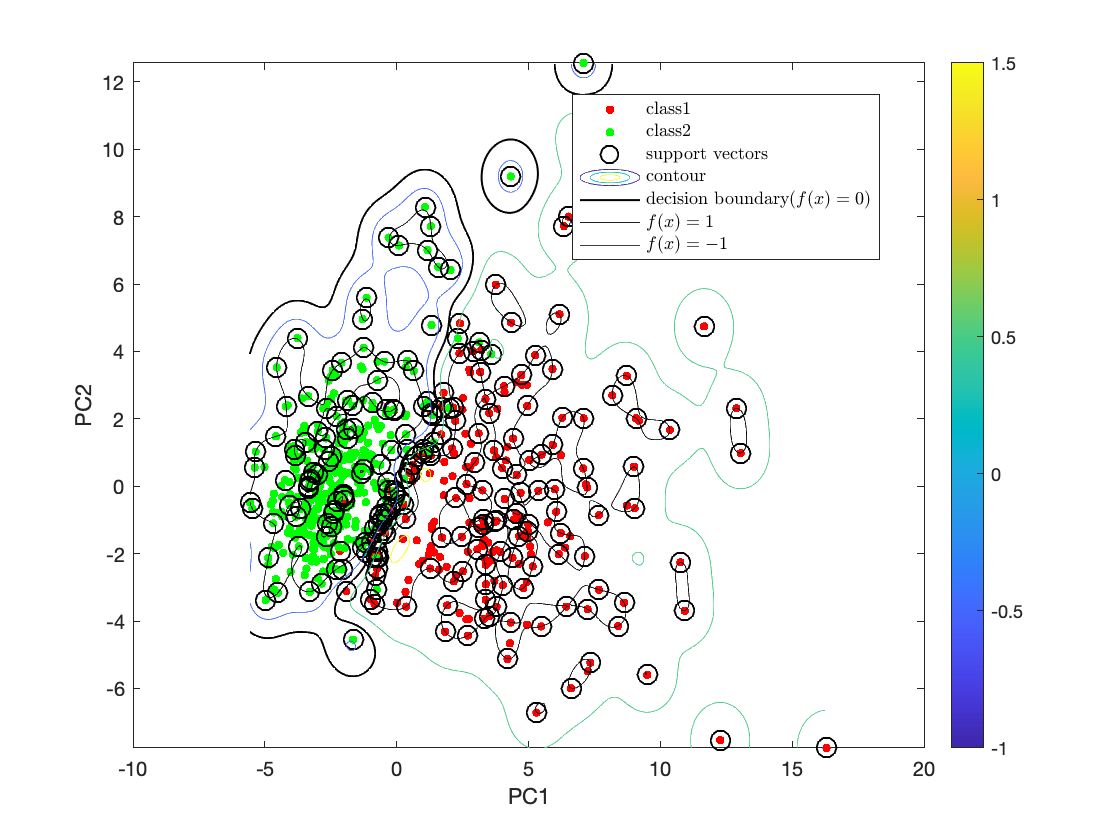

SVMModel = fitcsvm(X,Y, "BoxConstraint", 1, "KernelFunction", "gaussian");
svInd = SVMModel.IsSupportVector; 
h = 0.1; % Mesh grid step size
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)), min(X(:,2)):h:max(X(:,2))); % calculate grid points
[~,score] = SVMModel.predict([X1(:),X2(:)]);  % calculate scores at the each grid point
scoreGrid = reshape(score(:,2),size(X1,1),size(X2,2)); 
figure
gscatter(X(:,1), X(:,2), Y, 'rg');
hold on
plot(X(svInd,1),X(svInd,2),'ko','MarkerSize',10, "LineWidth",1) % Mark support vectors
contour(X1,X2,scoreGrid); % draw contour 
contour(X1,X2,scoreGrid, [0 0],'k', "LineWidth", 1); %draw decision bounday
contour(X1,X2,scoreGrid, [1 1],'k'); %draw f(x)=1
contour(X1,X2,scoreGrid, [-1 -1],'k'); %draw f(x)=-1
colorbar;
xlabel('PC1')
ylabel('PC2')
legend(["class1", "class2", "support vectors", "contour", "decision boundary($f(x)=0$)", "$f(x)=1$", "$f(x)=-1$"], "Interpreter","latex");
hold off

大まかに診断結果の良・悪を分類することができていることがわかる．

今度はグリッドサーチにより，ハイパーパラメータの最適化を試みる．

|=======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  |              |              |
|=======================================================================================|
|    1 | Best   |     0.37258 |     0.25355 |     0.37258 |       2.1544 |     0.021544 |
|    2 | Best   |     0.34271 |    0.090927 |     0.34271 |       2.1544 |          0.1 |
|    3 | Accept |     0.37258 |    0.091739 |     0.34271 |       215.44 |        0.001 |
|    4 | Accept |     0.37258 |    0.078593 |     0.34271 |      0.46416 |         1000 |
|    5 | Accept |     0.37258 |    0.095687 |     0.34271 |       215.44 |     0.021544 |
|    6 | Accept |     0.37258 |    0.073551 |     0.34271 |     0.021544 |         1000 |
|    7 | Accept |     0.37258 |    0.074726 |     0.34271 |           10 |     0.021544 |
|    8 | A

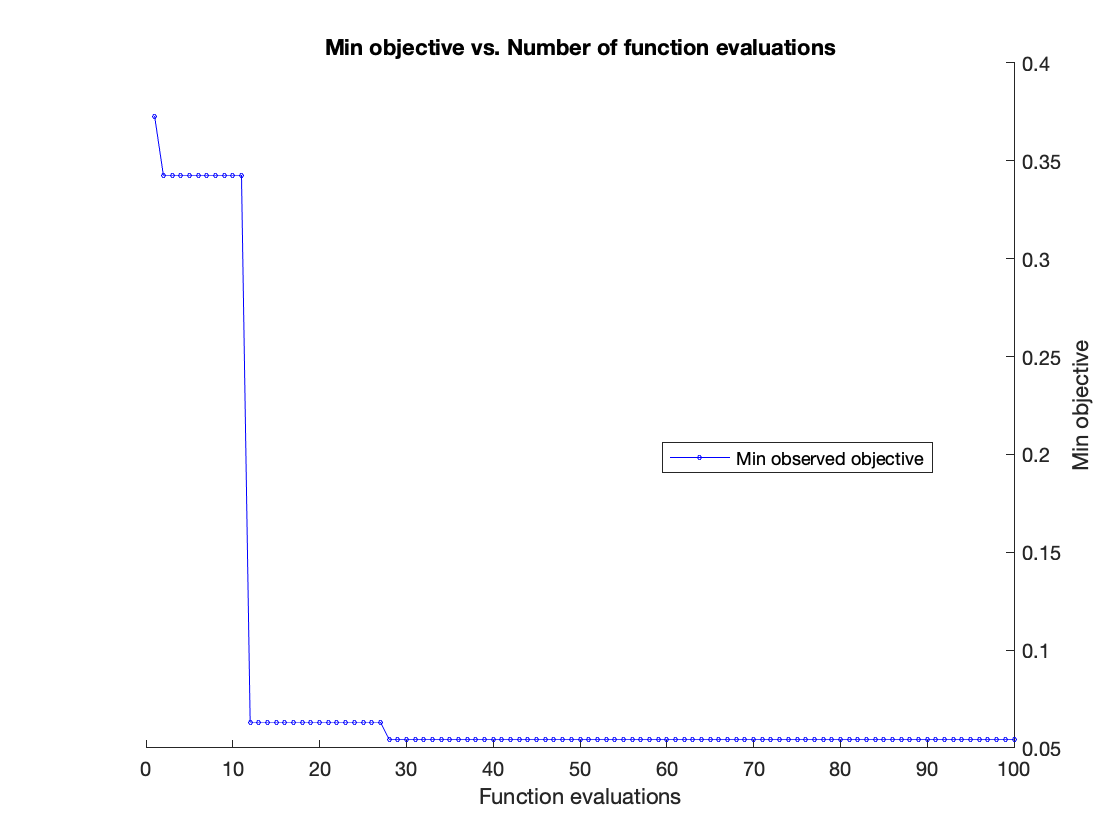


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 21.6349 seconds
Total objective function evaluation time: 7.6838

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

        1000           46.416   

Observed objective function value = 0.054482
Function evaluation time = 0.065795



SVMModel = fitcsvm(X, Y, "KernelFunction", "gaussian", ...
    'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus', "Optimizer", "gridsearch"));

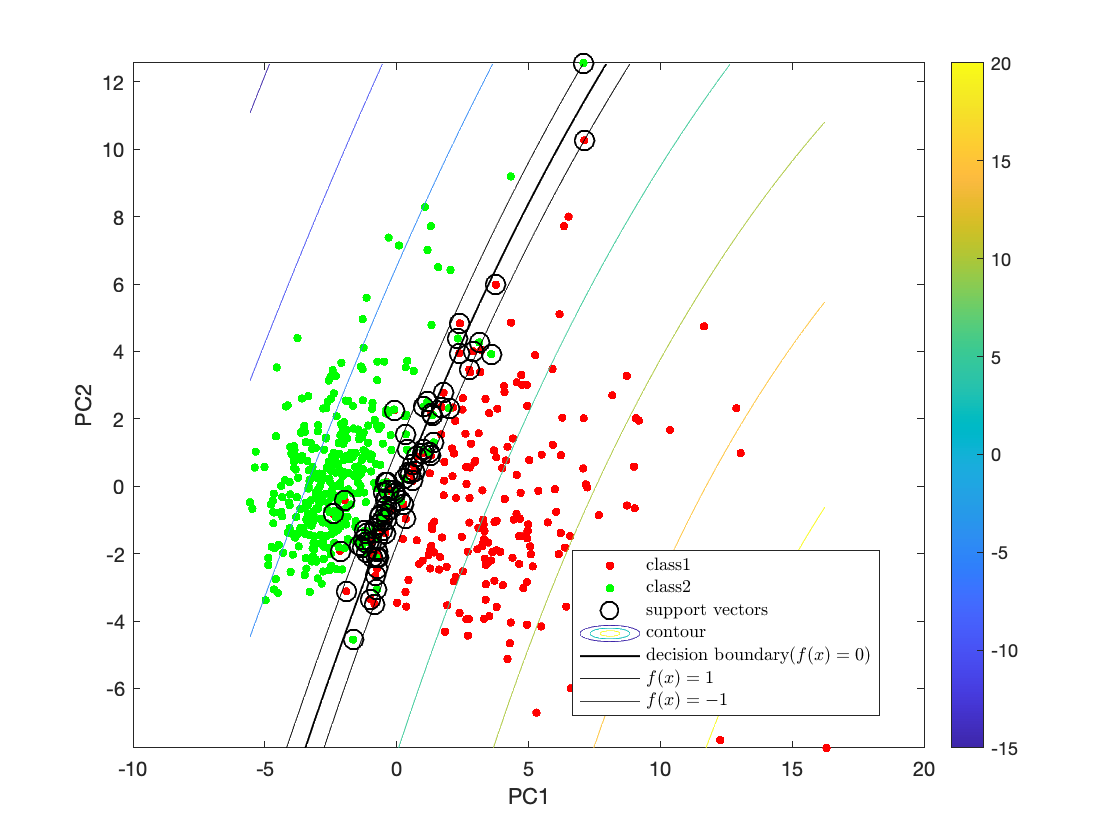

svInd = SVMModel.IsSupportVector; 
h = 0.1; % Mesh grid step size
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)), min(X(:,2)):h:max(X(:,2))); % calculate grid points
[~,score] = SVMModel.predict([X1(:),X2(:)]);  % calculate scores at the each grid point
scoreGrid = reshape(score(:,2),size(X1,1),size(X2,2)); 
figure
gscatter(X(:,1), X(:,2), Y, 'rg');
hold on
plot(X(svInd,1),X(svInd,2),'ko','MarkerSize',10, "LineWidth",1) % Mark support vectors
contour(X1,X2,scoreGrid); % draw contour 
contour(X1,X2,scoreGrid, [0 0],'k', "LineWidth", 1); %draw decision bounday
contour(X1,X2,scoreGrid, [1 1],'k'); %draw f(x)=1
contour(X1,X2,scoreGrid, [-1 -1],'k'); %draw f(x)=-1
colorbar;
xlabel('PC1')
ylabel('PC2')
legend(["class1", "class2", "support vectors", "contour", "decision boundary($f(x)=0$)", "$f(x)=1$", "$f(x)=-1$"], "Interpreter","latex");
hold off

パラメータを最適化することで，上記の図のようにデータから診断結果の２クラスに分類できていることがわかる．